%% Multi-Agent Ring Road - LIVE Simulation (ADT + MPC)
% Renders the simulation in real-time using the Automated Driving Toolbox.

clear; clc; close all;
yalmip('clear');

%% 1. Simulation & Road Parameters
dt    = 0.1;       % Faster step for smoother visuals
Tsim  = 60;        % Total time
M     = 10;        % Number of vehicles
L_track = 250;     % Track length (m)
R = L_track / (2*pi);

% Controller Parameters
v_target = 10;     % 10 m/s
d0 = 5.0; h = 1.2; % Safety gap
N_hor = 20;        % Horizon

%% 2. Setup Automated Driving Toolbox Scenario
scenario = drivingScenario;
scenario.SampleTime = dt;
scenario.StopTime = Tsim;

% Create Ring Road (Visuals)
theta_road = linspace(0, 2*pi, 200)';
road_x = R * cos(theta_road);
road_y = R * sin(theta_road);
road(scenario, [road_x, road_y, zeros(size(road_x))], 'Lanes', lanespec(1, 'Width', 6));

% Create Vehicles (Visuals Only - Physics controlled by us)
adt_cars = cell(1, M);
for i = 1:M
    adt_cars{i} = vehicle(scenario, ...
        'ClassID', 1, 'Length', 4.5, 'Width', 2.0, 'Mesh', driving.scenario.carMesh, ...
        'PlotColor', [0 1 0]); % Start Green
end

% Initialize Viewer
hFig = figure('Position', [100, 100, 1000, 800]);
hAx = axes('Parent', hFig);
plot(scenario, 'Parent', hAx);
view(hAx, 30, 45); axis(hAx, 'equal'); xlim(hAx, [-R-20 R+20]); ylim(hAx, [-R-20 R+20]);
hLight = light(hAx, 'Position',[-R -R 50],'Style','local');
title(hAx, 'Live MPC Ring Road Simulation');

%% 3. Initialize State Variables (Internal Physics)
% We keep our own physics state because ADT doesn't handle 
% the "teleport wrap-around" logic nicely.
x_curr = zeros(M,1);
v_curr = ones(M,1) * v_target;
dist_init = L_track / M;

for i = 1:M
    x_curr(i) = L_track - (i-1)*dist_init; 
end

%% 4. Build MPC Controller (Optimizer Object)
% (Same efficient YALMIP setup as before)
a_plus  = sdpvar(N_hor, 1); a_minus = sdpvar(N_hor, 1);
v_opt   = sdpvar(N_hor+1, 1); p_opt   = sdpvar(N_hor+1, 1); s_opt   = sdpvar(N_hor, 1);
a_net = a_plus - a_minus;

p_init_var = sdpvar(1,1); v_init_var = sdpvar(1,1); p_lead_traj = sdpvar(N_hor+1, 1);

% Weights & Bounds
w_traction = 10; w_regen = 2; w_v = 5; w_d = 20; w_s = 10000;
amin = -3.5; amax = 2.0; vmax = 20; vmin = 0; smax = 20;

constraints = [p_opt(1) == p_init_var, v_opt(1) == v_init_var];
constraints = [constraints, amin <= a_net <= amax, vmin <= v_opt <= vmax, 0 <= s_opt <= smax];
constraints = [constraints, a_plus >= 0, a_minus >= 0];

obj = 0;
for k = 1:N_hor
    constraints = [constraints, v_opt(k+1) == v_opt(k) + a_net(k)*dt];
    constraints = [constraints, p_opt(k+1) == p_opt(k) + v_opt(k)*dt + 0.5*a_net(k)*dt^2];
    constraints = [constraints, p_lead_traj(k+1) - p_opt(k+1) + s_opt(k) >= d0 + h*v_opt(k+1)];
    
    obj = obj + w_traction*(a_plus(k)^2) + w_regen*(a_minus(k)^2) + ...
          w_v*(v_opt(k+1)-v_target)^2 + w_s*s_opt(k)^2 + ...
          w_d*((p_lead_traj(k+1) - p_opt(k+1)) - (d0 + h*v_opt(k+1)))^2;
end

controller = optimizer(constraints, obj, sdpsettings('solver','gurobi','verbose',0), ...
                       {p_init_var, v_init_var, p_lead_traj}, a_net);

%% 5. LIVE SIMULATION LOOP
fprintf('Starting Live Simulation with an IDIOT Driver...\n');

Starting Live Simulation with an IDIOT Driver...


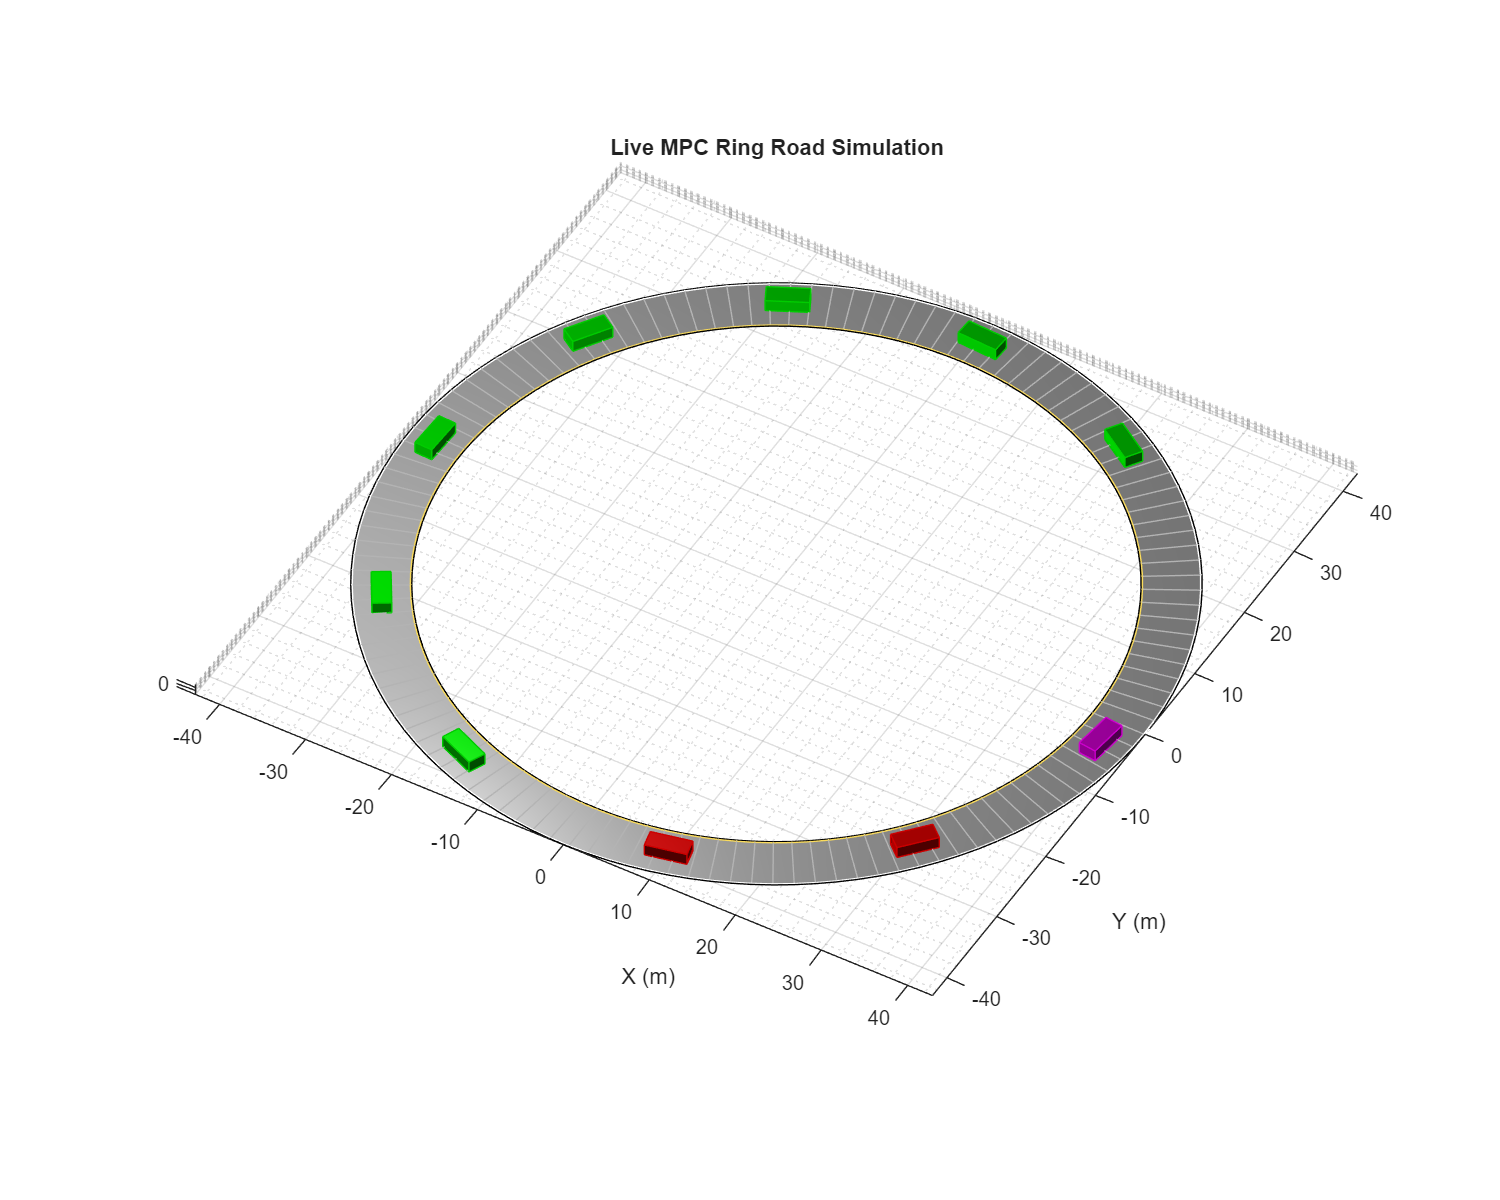


% Define the Idiot
id_idiot = 5; 
idiot_mode = 'sinusoidal'; % Options: 'sinusoidal', 'brake_check', 'random'

while advance(scenario)
    
    t = scenario.SimulationTime;
    
    % -- A. MPC & CONTROL CALCULATION --
    u_control = zeros(M,1);
    
    for i = 1:M
        % 1. Identify Leader & Wrap-around
        if i == 1
            id_lead = M; offset = L_track;
        else
            id_lead = i - 1; offset = 0;
        end
        
        % 2. Get Leader State
        p_L_0 = x_curr(id_lead) + offset;
        v_L_0 = v_curr(id_lead);
        
        % --- THE IDIOT LOGIC ---
        if i == id_idiot
            % This driver ignores safety and optimization!
            switch idiot_mode
                case 'sinusoidal'
                    % Accelerates and brakes in a wave (annoying phantom jam creator)
                    u_control(i) = 2.0 * sin(0.5 * t); 
                    
                case 'brake_check'
                    % Drives normal, then slams brakes at t=10s
                    if t > 10 && t < 12
                        u_control(i) = -3.5; % FULL BRAKE
                    else
                        % Simple cruise control (P-controller)
                        u_control(i) = 1.0 * (v_target - v_curr(i));
                    end
                    
                case 'random'
                    % Complete chaos
                    u_control(i) = -2 + 4*rand(); 
            end
            
            % Mechanical Limits (cars can't fly)
            u_control(i) = max(amin, min(amax, u_control(i)));
            
        else
            % --- NORMAL MPC LOGIC (Everyone else) ---
            traj_L = p_L_0 + v_L_0 * (0:N_hor)' * dt; % Constant Vel Prediction
            
            inputs = {x_curr(i), v_curr(i), traj_L};
            [sol, err] = controller(inputs);
            
            if err
                u_control(i) = -1.0; % Safe fallback
            else
                val = sol(1);
                if isnan(val) || isinf(val), val = 0; end
                u_control(i) = val;
            end
        end
    end
    
    % -- B. PHYSICS UPDATE --
    for i = 1:M
        v_next = v_curr(i) + u_control(i)*dt;
        v_next = max(0, v_next); 
        x_next = x_curr(i) + v_curr(i)*dt + 0.5*u_control(i)*dt^2;
        
        v_curr(i) = v_next;
        x_curr(i) = x_next;
        
        % -- C. VISUALIZATION --
        s_vis = mod(x_curr(i), L_track);
        theta = s_vis / R;
        pos_x = R * cos(theta);
        pos_y = R * sin(theta);
        yaw_deg = (theta + pi/2) * (180/pi);
        
        adt_cars{i}.Position = [pos_x, pos_y, 0];
        adt_cars{i}.Yaw      = yaw_deg;
        
        % -- COLOR LOGIC --
        if i == id_idiot
            adt_cars{i}.PlotColor = [1 0 1]; % PURPLE for the Idiot
        elseif u_control(i) < -0.5
            adt_cars{i}.PlotColor = [1 0 0]; % Red (Braking)
        else
            spd_norm = max(0, min(1, v_curr(i)/v_target));
            adt_cars{i}.PlotColor = [0, spd_norm, 1-spd_norm]; 
        end
    end
    
    drawnow limitrate;
    if ~ishandle(hFig), break; end
end


fprintf('Simulation Finished.\n');

Simulation Finished.
